# Pendulum Simulation

## Simulating Dynamics without Control

### Paramters

clc;clear;close all;

% Gravity (m/s^2)
g = 9.81;
% length
l = 0.1;
% mass 
m = 0.1;
% spring constant
k=0.25;

% Simulation time span (s) 
T = 1e-4;
t_span = 0:T:10;

### Initial Conditions

x0 = l;
x0_dot = 0;
theta0 = pi/2;
theta0_dot = 0;

% Initialize state vector
x0 = [x0, x0_dot, theta0, theta0_dot]

x0 =     0.1000         0    1.5708         0


### Solving the ODEs

% Use ode45 to solve for x_dot for your defined time span 
[t_actual,x_actual] = ode45(@(t,x) pendODEs(t,x,m,l,k,g),t_span,x0);

### Plot the Results

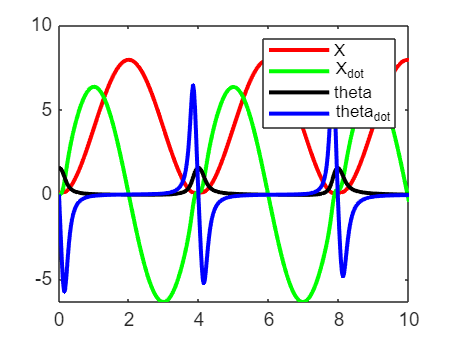

% Plot the results over the time span
plot(t_actual,x_actual(:,1),"red",t_actual,x_actual(:,2),"green",t_actual,x_actual(:,3),"black",t_actual,x_actual(:,4),"blue",LineWidth=2)
legend("X", "X_{dot}", "theta", "theta_{dot}");

## Simulating Dynamics with Control

### Setting up State Space Equations

% Using the same state vector defined in "pendODEs.m" (redefine it here), find the A,B, and C state space matricies.

syms pos pos_dot theta theta_dot

% State vector 
X = [pos;pos_dot;theta;theta_dot]

$$X = \left(\begin{array}{c} \mathrm{pos}\\ \dot{\mathrm{pos}}\\ \theta \\ \dot{\theta } \end{array}\right)$$


% Equilibrium Point
X0 = zeros(4,1);

% for ease
c_P = cos(theta);
s_P = sin(theta);

% State vector
f = [pos_dot;
    (l+pos)*theta_dot^2+g*c_P-k/m*pos;
    theta_dot;
    (-2*pos_dot*theta_dot-g*s_P)/(l+pos);
]

$$f = \left(\begin{array}{c} \dot{\mathrm{pos}}\\ \left(\mathrm{pos}+\frac{1}{10}\right)\,{\dot{\theta }}^{2}-\frac{5\,\mathrm{pos}}{2}+\frac{981\,\cos\left(\theta \right)}{100}\\ \dot{\theta }\\ -\frac{\frac{981\,\sin\left(\theta \right)}{100}+2\,\dot{\mathrm{pos}}\,\dot{\theta }}{\mathrm{pos}+\frac{1}{10}} \end{array}\right)$$


% Finding A, B, C (to linearize, we need to use the jacobian)
A = jacobian(f,X)

$$A = \begin{array}{l} \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ {\dot{\theta }}^{2}-\frac{5}{2} & 0 & -\sigma_{1} & 2\,\dot{\theta }\,\left(\mathrm{pos}+\frac{1}{10}\right)\\ 0 & 0 & 0 & 1\\ \frac{\sigma_{1}+2\,\dot{\mathrm{pos}}\,\dot{\theta }}{{\left(\mathrm{pos}+\frac{1}{10}\right)}^{2}} & -\frac{2\,\dot{\theta }}{\mathrm{pos}+\frac{1}{10}} & -\frac{981\,\cos\left(\theta \right)}{100\,\left(\mathrm{pos}+\frac{1}{10}\right)} & -\frac{2\,\dot{\mathrm{pos}}}{\mathrm{pos}+\frac{1}{10}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{981\,\sin\left(\theta \right)}{100} \end{array}$$

A_eq = subs(A,X,X0)

$$A\_eq = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ -\frac{5}{2} & 0 & 0 & 0\\ 0 & 0 & 0 & 1\\ 0 & 0 & -\frac{981}{10} & 0 \end{array}\right)$$

B_eq = [0; 0; 0; 0] %assuming no input

B_eq =      0
     0
     0
     0


C = [0 0 1 0]; %reading theta
D = [0];

% discritze!
% ...

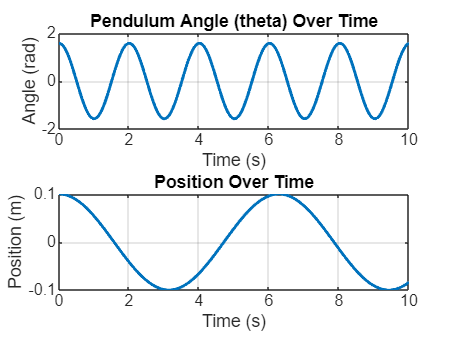


syms pos pos_dot theta theta_dot real
g = 9.81;  % Gravity (m/s^2)
k = 1;     % Spring constant (N/m)
m = 1;     % Mass (kg)
l = 1;     % Length (m)

% State vector
X = [pos; pos_dot; theta; theta_dot];

% Equilibrium Point
X0 = zeros(4,1);

% Trigonometric functions
c_P = cos(theta);
s_P = sin(theta);

% State vector dynamics
f = [pos_dot;
     (l + pos) * theta_dot^2 + g * c_P - k/m * pos;
     theta_dot;
     (-2 * pos_dot * theta_dot - g * s_P) / (l + pos)];
 
% Jacobian to find A matrix
A = jacobian(f, X);

% Substituting equilibrium point X0 into A
A_eq = subs(A, X, X0);
A_eq = double(A_eq); % Converting to numerical values

% B matrix (no input)
B_eq = [0; 0; 0; 0];

% C matrix (reading theta)
C = [0 0 1 0]; 

% D matrix
D = [0];

% Discretization parameters
Ts = 0.01;  % Sampling time (s)

% Continuous-time state-space model
sys_cont = ss(A_eq, B_eq, C, D);

% Discretize the system
sys_disc = c2d(sys_cont, Ts, 'zoh');

% Simulation time
T_end = 10; % 10 seconds
time = 0:Ts:T_end;

% Initial condition (modify as needed)
X0_sim = [0.1; 0; pi/2; 0]; % Initial position, velocity, angle, angular velocity

% Simulate the response of the system
[Y, t, X_disc] = lsim(sys_disc, zeros(size(time)), time, X0_sim);

%% Plotting the results
% Pendulum Angle (theta) and Position (pos) over Time

% Create a figure for the plots
figure;
subplot(2, 1, 1);
plot(t, X_disc(:,3), 'LineWidth', 1.5); % theta (angle) over time
title('Pendulum Angle (theta) Over Time');
xlabel('Time (s)');
ylabel('Angle (rad)');
grid on;

subplot(2, 1, 2);
plot(t, X_disc(:,1), 'LineWidth', 1.5); % position over time
title('Position Over Time');
xlabel('Time (s)');
ylabel('Position (m)');
grid on;